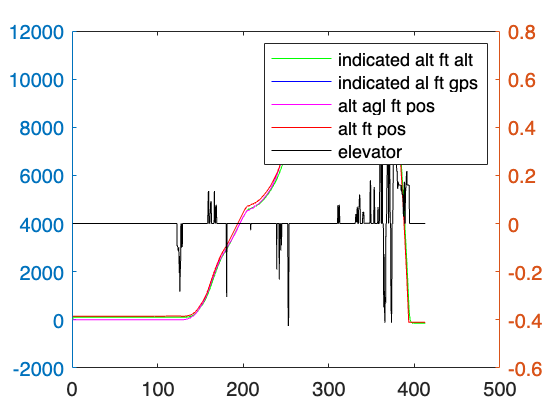

syms x y;
eqn = x^2/x;
simplify(eqn);
subs(eqn,"x",2);

% Load the sensor data from the .csv file.
% data = readmatrix("./data-collection/Sample_Log_2022_05_09.csv");
data = readmatrix("./data-collection/Pitch_Crash_2022_05_10.csv");

[row, col]= size(data);

time = data(:,1);
indicated_alt_ft_alt = data(:,57); %modeled based on an altimeter
indicated_alt_ft_gps = data(:,82);
alt_agl_ft_pos = data(:,20); %above ground level
alt_ft_pos = data(:,21); %absolute

elevator = data(:,8);

figure
yyaxis left;
plot(time,indicated_alt_ft_alt,'g-',time,indicated_alt_ft_gps,'b-',time,alt_agl_ft_pos,'m-',time,alt_ft_pos,'r-');

yyaxis right;
plot(time,elevator,'black-')

legend(["indicated alt ft alt" "indicated al ft gps" "alt agl ft pos" "alt ft pos" "elevator"]);